# **Script comparing performance of the old style (@coneMosaicHex-based) to the new style (@cMosaic-based) cone mosaic**

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2022*

# **Step 1.** Generate treeshrew optics

theOI = oiTreeShrewCreate('pupilDiameterMM', 2.0);
micronsPerDegree = theOI.optics.micronsPerDegree;

# **Step 2.** Generate new- and old-style tree shrew cone mosaics

% Our scene will be 8 degrees wide
sceneFOVdegs = 8.0;

% Our mosaics will be 5x5 degrees
mosaicFOVdegs = [5 5];

% Old way of generating a @coneMosaicHex for the threeshrew
theOldStyleTreeShrewConeMosaic = coneMosaicTreeShrewCreate(...
    micronsPerDegree, ...
    'fovDegs', mosaicFOVdegs , ...
    'integrationTime', 500/1000);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 2087
Scones after making an S-cone free central patch: 2087 (added Lcones:0, added Mcones:0)
Scones after pass 1: 1241 (added Lcones:1125, added Mcones:0)
Scones after pass 2: 734 (added Lcones:670, added Mcones:0)
Scones after pass 3: 440 (added Lcones:394, added Mcones:0)
Scones after pass 4: 280 (added Lcones:219, added Mcones:0)
Scones after pass 5: 230 (added Lcones:55, added Mcones:0)
Scones after pass 6: 226 (added Lcones:4, added Mcones:0)
Scones after pass 7: 226 (added Lcones:0, added Mcones:0)



% New way of generating a @cMosaic for the treeshrew
theNewStyleTreeShrewConeMosaic = cMosaicTreeShrewCreate(...
    'fovDegs', mosaicFOVdegs , ...
    'integrationTime', 500/1000);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 2087
Scones after making an S-cone free central patch: 2087 (added Lcones:0, added Mcones:0)
Scones after pass 1: 1227 (added Lcones:1120, added Mcones:0)
Scones after pass 2: 733 (added Lcones:677, added Mcones:0)
Scones after pass 3: 445 (added Lcones:411, added Mcones:0)
Scones after pass 4: 270 (added Lcones:213, added Mcones:0)
Scones after pass 5: 226 (added Lcones:49, added Mcones:0)
Scones after pass 6: 218 (added Lcones:9, added Mcones:0)
Scones after pass 7: 216 (added Lcones:2, added Mcones:0)
Scones after pass 8: 215 (added Lcones:1, added Mcones:0)
Scones after pass 9: 215 (added Lcones:0, added Mcones:0)


theConeMosaicHex =   0×0 coneMosaicHex array with properties:

            eccBasedConeQuantalEfficiency: 0
                   eccBasedMacularPigment: 0
                                lambdaMin: 2
                                lambdaMid: 2
                             customLambda: 6.2000
               customInnerSegmentDiameter: 6
                      eccBasedConeDensity: 0
          coneEfficiencyCorrectionFactors: []
                            apertureStats: []
                         resamplingFactor: 3
                                  marginF: 1
                   sConeMinDistanceFactor: 2.5000
                   sConeFreeRadiusMicrons: 0
                         coneTypesHexGrid: [4175×1 double]
                          coneLocsHexGrid: [4175×2 double]
              coneLocsOriginatingRectGrid: [2304×2 double]
               patternOriginatingRectGrid: [48×48 double]
     patternSampleSizeOriginatingRe

Achieved cone densities: L (0.949), M (0.000), S (0.051), K (0.000)


theCMosaic =   cMosaic with properties:

                                        LCONE_ID: 1
                                        MCONE_ID: 2
                                        SCONE_ID: 3
                                        KCONE_ID: 4
                                       opticDisk: [1×1 struct]
                                            name: 'cone mosaic'
                                         pigment: [1×1 cPhotoPigment]
                                         macular: [1×1 Macular]
                rodIntrusionAdjustedConeAperture: 0
                          eccVaryingConeAperture: 1
                              eccVaryingConeBlur: 0
                    eccVaryingOuterSegmentLength: 1
                 eccVaryingMacularPigmentDensity: 1
          eccVaryingMacularPigmentDensityDynamic: 0
    anchorAllEccVaryingParamsToTheirFovealValues: 0
                                 integrationTime: 0.5000
     

# **Step 3. Display the 2 mosaics**

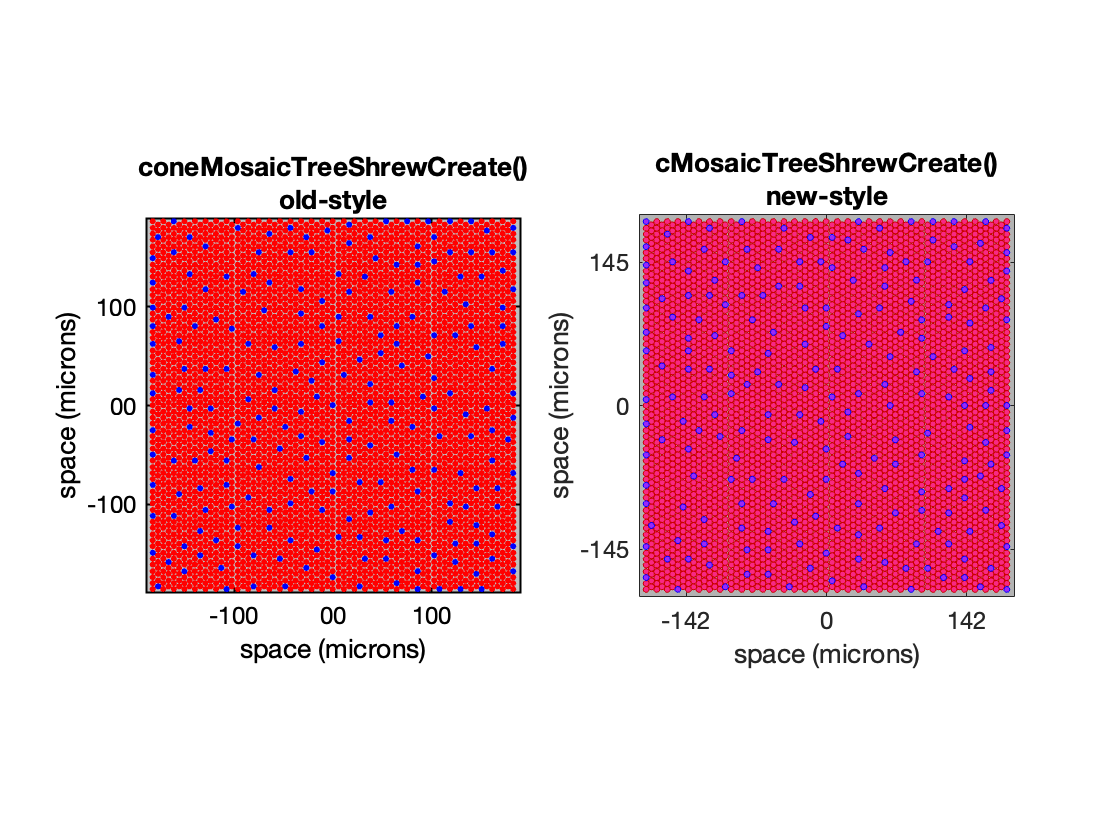

% Display the old and the new cone mosaics
hFig = figure(1);
ax = subplot(1,2,1);
theOldStyleTreeShrewConeMosaic.visualizeGrid(...
    'axesHandle', ax, ...
    'ticksInMicrons', true, ...
    'visualizedConeAperture',  'lightCollectingArea', ...
    'plotTitle', sprintf('coneMosaicTreeShrewCreate()\nold-style'));
set(ax,'fontSize', 12);
  

ax = subplot(1,2,2);
theNewStyleTreeShrewConeMosaic.visualize(...
    'figureHandle', hFig, ...
    'axesHandle', ax, ...
    'domain', 'microns', ...
    'visualizedConeAperture',  'lightCollectingArea', ...
    'plotTitle', sprintf('cMosaicTreeShrewCreate()\nnew-style'), ...
    'fontSize', 12);

# **Step 4.** Compute the optical image for a sinusoid stimulus

% Create presentation display and place it 5 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 5/100);

% parameter struct for a low spatial frequency Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 5.0, ... % 5.0 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 0, ...                     % spatial phase degrees, 0 = cos, 90 = sin
    'sizeDegs', sceneFOVdegs, ...           
    'sigmaDegs', 3, ...                    % sigma of Gaussian envelope
    'contrast', 0.9,...                     % 0.9 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );

% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 5);

theOI = oiCompute(realizedStimulusScene, theOI);


# **Step 5.** Compute 256 response instances with the old- and the new-style cone mosaics

% Generate 256 response instances
nTrialsNum = 256;
emPath = zeros(nTrialsNum, 1, 2);

% Compute the cone mosaic activation
t1 = clock();
[~,theCMosaicActivationInstances] = theNewStyleTreeShrewConeMosaic.compute(...
    theOI, 'nTrials', nTrialsNum); 
t2 = clock();
newStyleComputeTime = etime(t2,t1);


t1 = clock();
theConeMosaicHexActivationInstances = theOldStyleTreeShrewConeMosaic.compute(...
    theOI, 'emPath', emPath); 
t2 = clock();
oldStyleComputeTime = etime(t2,t1);


# **Step 6.** Compare performance and results

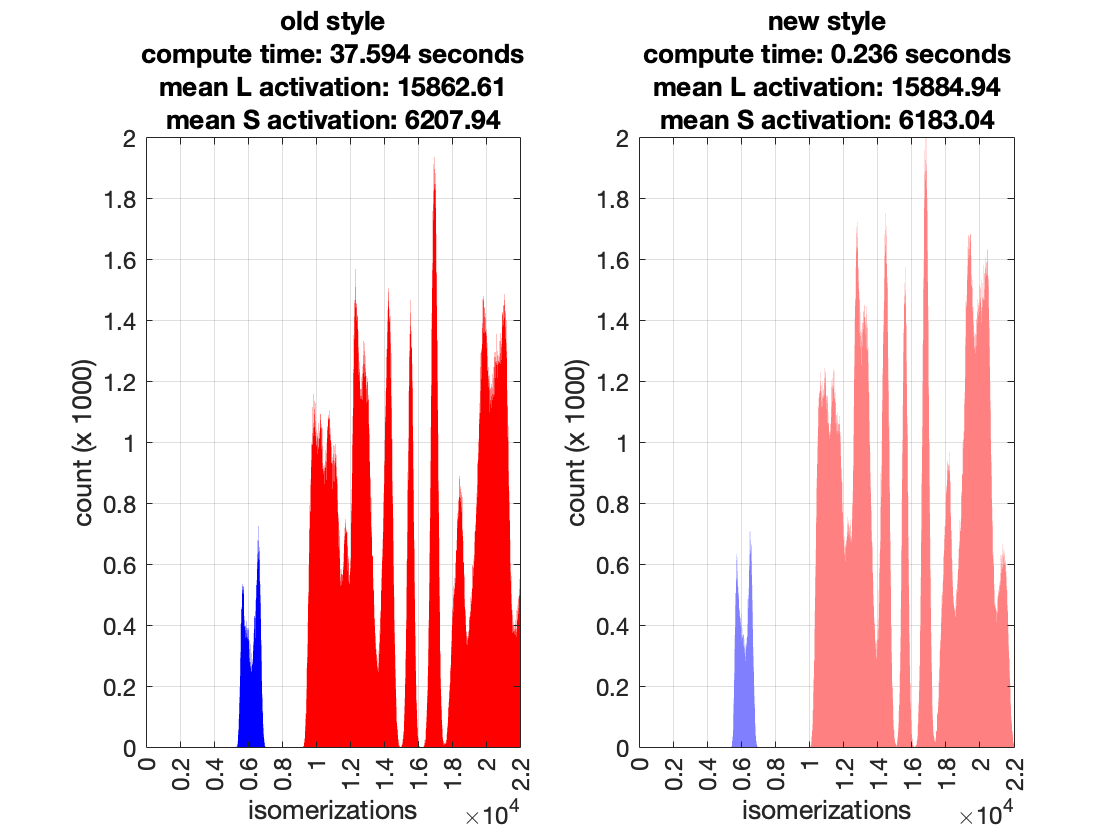

% Retrieve the new-style cone mosaic responses
% L-cone response instances 
theCMosaicLconeActivations = ...
    squeeze(theCMosaicActivationInstances(:, 1, theNewStyleTreeShrewConeMosaic.lConeIndices));
% M-cone response instances
theCMosaicSconeActivations = ...
    squeeze(theCMosaicActivationInstances(:, 1, theNewStyleTreeShrewConeMosaic.sConeIndices));


% Retrieve the old-style cone mosaic responses
lConeIndices = find(theOldStyleTreeShrewConeMosaic.pattern == 2);
sConeIndices = find(theOldStyleTreeShrewConeMosaic.pattern == 4);
theConeMosaicHexLconeActivations = zeros(nTrialsNum, numel(lConeIndices));
theConeMosaicHexSconeActivations = zeros(nTrialsNum, numel(sConeIndices));

for i = 1:nTrialsNum
    theActivation = squeeze(theConeMosaicHexActivationInstances(i,:,:));
    theConeMosaicHexLconeActivations(i,:) = theActivation(lConeIndices);
    theConeMosaicHexSconeActivations(i,:) = theActivation(sConeIndices);
end

% Plot histograms of the L- and S-cone responses for the old- and the new-
% style cone mosaics
bins = (min(theCMosaicActivationInstances(:))-50):10:(max(theCMosaicActivationInstances(:))+50);
nL = histcounts(theConeMosaicHexLconeActivations(:), bins);
nS = histcounts(theConeMosaicHexSconeActivations(:), bins);

hFig = figure(2); clf;
ax = subplot(1,2,1);
bar(ax, bins(1:end-1), nL(:)/1000, 1, 'FaceColor',[1 0. 0.]);
hold(ax, 'on');
bar(ax, bins(1:end-1), nS(:)/1000, 1, 'FaceColor', [0. 0. 1]);
set(ax, 'FontSize', 12, 'XTick', (0:0.2:4)*1e4, 'XLim', 1e4*[0 2.2], 'YLim', [0 2], 'YTick', 0:0.2:5);
grid(ax, 'on');
xtickangle(ax, 90);
title(ax, sprintf('old style\ncompute time: %2.3f seconds\nmean L activation: %2.2f\nmean S activation: %2.2f', ...
    oldStyleComputeTime, mean(theConeMosaicHexLconeActivations(:)), mean(theConeMosaicHexSconeActivations(:))));
xlabel(ax, 'isomerizations');
ylabel(ax, 'count (x 1000)');


nL = histcounts(theCMosaicLconeActivations(:), bins);
nS = histcounts(theCMosaicSconeActivations(:), bins);

ax = subplot(1,2,2);
bar(ax, bins(1:end-1), nL(:)/1000, 1, 'FaceColor',[1 0.5 0.5]);
hold(ax, 'on');
bar(ax, bins(1:end-1), nS(:)/1000, 1, 'FaceColor', [0.5 0.5 1]);
set(ax, 'FontSize', 12, 'XTick', (0:0.2:4)*1e4, 'XLim', 1e4*[0 2.2], 'YLim', [0 2], 'YTick', 0:0.2:5);
grid(ax, 'on');
xtickangle(ax, 90);
title(ax, sprintf('new style\ncompute time: %2.3f seconds\nmean L activation: %2.2f\nmean S activation: %2.2f', ...
    newStyleComputeTime, mean(theCMosaicLconeActivations(:)), mean(theCMosaicSconeActivations(:))));
xlabel(ax, 'isomerizations');
ylabel(ax, 'count (x 1000)');

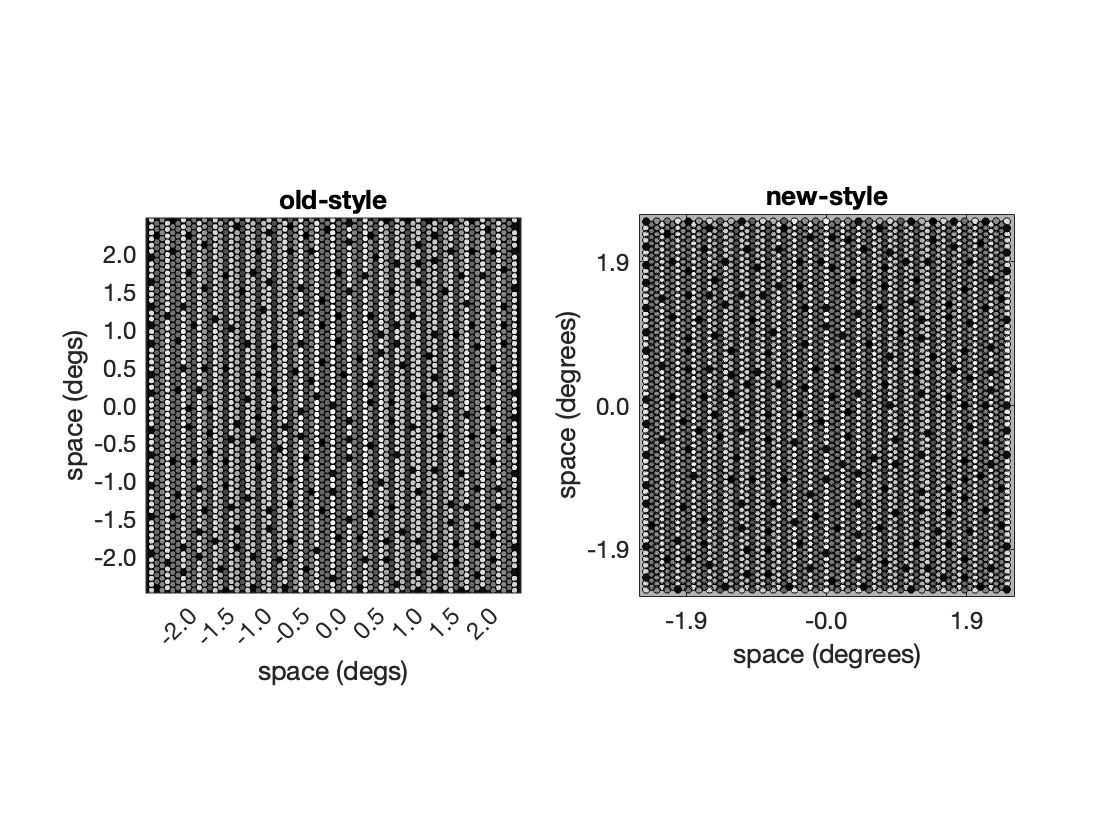



hFig = figure(3); clf;
meanConeMosaicHexActivation = squeeze(mean(theConeMosaicHexActivationInstances,1));
meanCMosaicActivation = squeeze(mean(theCMosaicActivationInstances,1));

ax = subplot(1,2,1);
theOldStyleTreeShrewConeMosaic.renderActivationMap(ax, ...
    meanConeMosaicHexActivation, ...
    'mapType', 'modulated disks');
title(ax, 'old-style');
set(ax, 'FontSize', 12);

ax = subplot(1,2,2);
theNewStyleTreeShrewConeMosaic.visualize(...
    'figureHandle', hFig, ...
    'axesHandle', ax, ...
    'activation', meanCMosaicActivation, ...
    'plotTitle', sprintf('new-style'), ...
    'fontSize', 12);